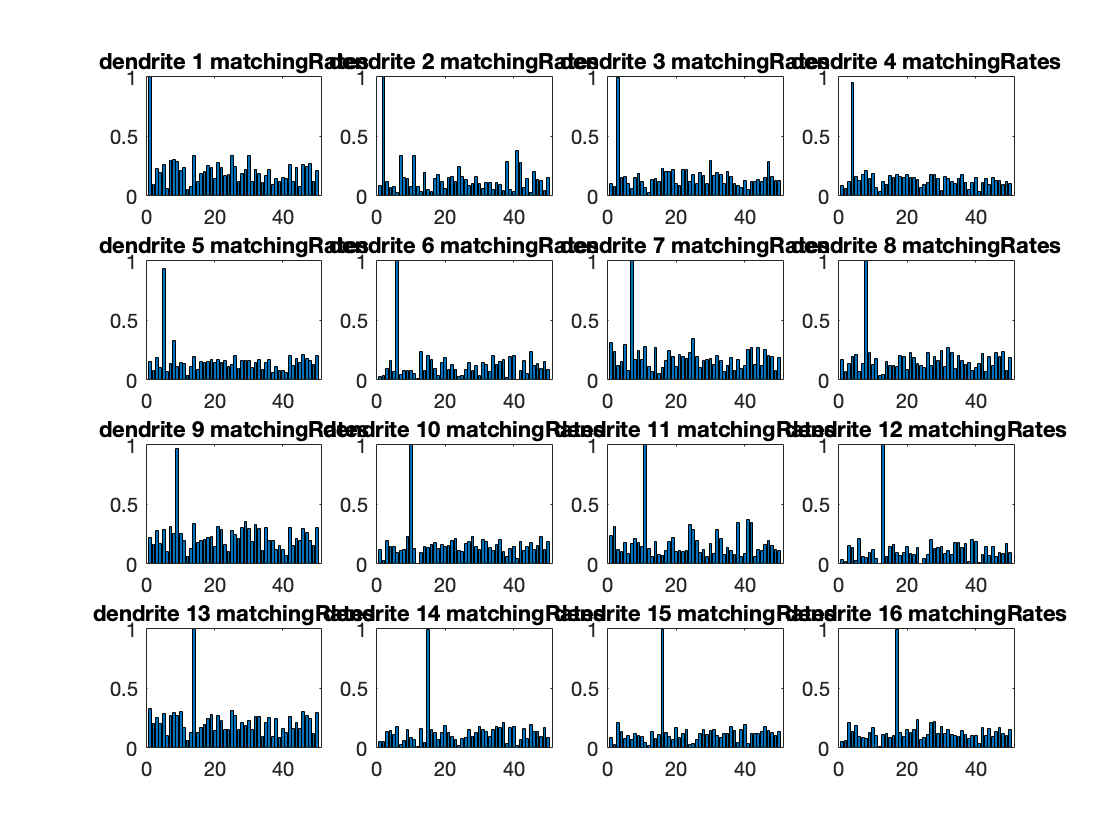

temp = 0;
for index = 1:17
    if index == 12
        continue
    end
    temp = temp + 1;
    eval(['load impuf50x50compareResult' num2str(index) '.mat']);
    subplot(4,4,temp)
    bar(Rmat)
    eval(['title ("dendrite ' num2str(temp) ' matchingRates")']);
end

Center1 at [400, 400], radius = 3.450000e+01
Center1 at [400, 400], radius = 3.450000e+01
the last matchingRate Difference is 4.430000e+01 !
the last matchingRate Difference is 8.200000e+00 !
the last matchingRate Difference is 8.200000e-01 !
the last matchingRate Difference is 1.560000e-01 !
the last matchingRate Difference is 4.220000e-02 !
the last matchingRate Difference is 1.450000e-02 !
the last matchingRate Difference is 5.940000e-03 !


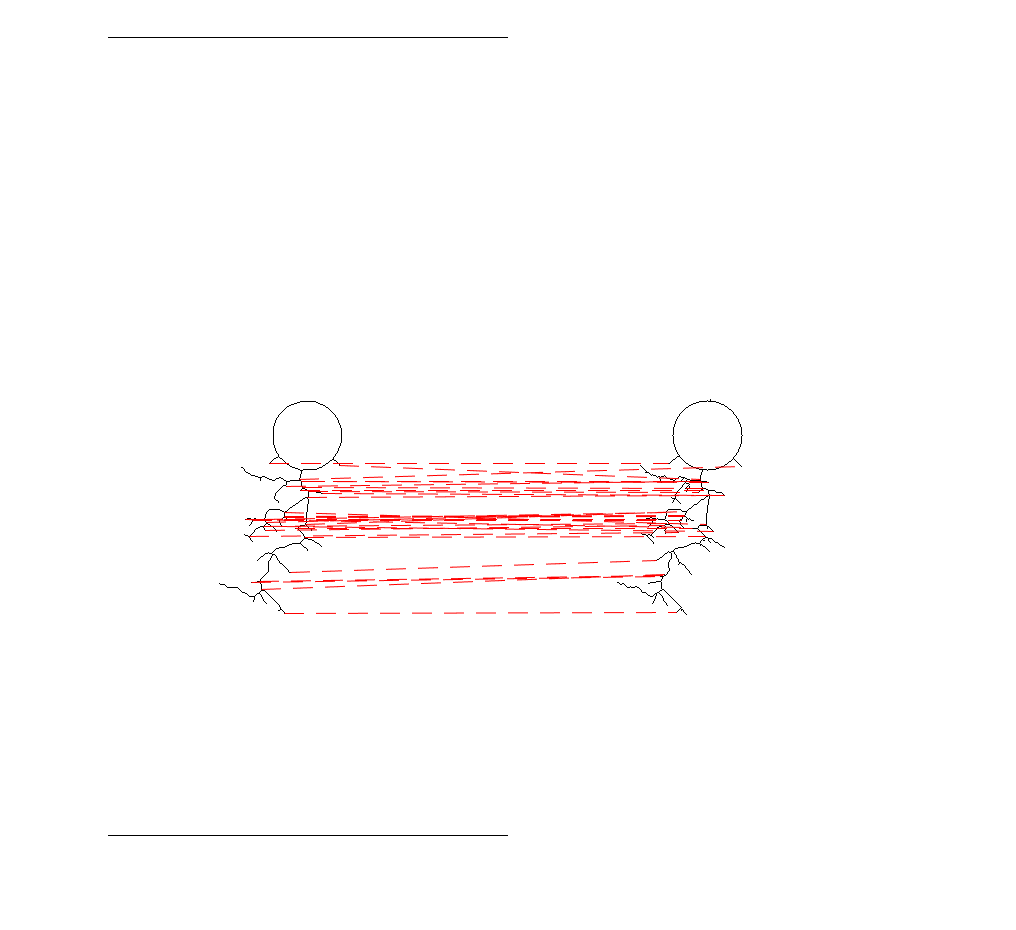

H_mat =    -0.0054    0.0007    0.6905
   -0.0030   -0.0019    0.7233
   -0.0000    0.0000   -0.0011


H_mat =    -0.0003   -0.0008   -0.6942
    0.0031   -0.0041   -0.7197
    0.0000   -0.0000   -0.0047


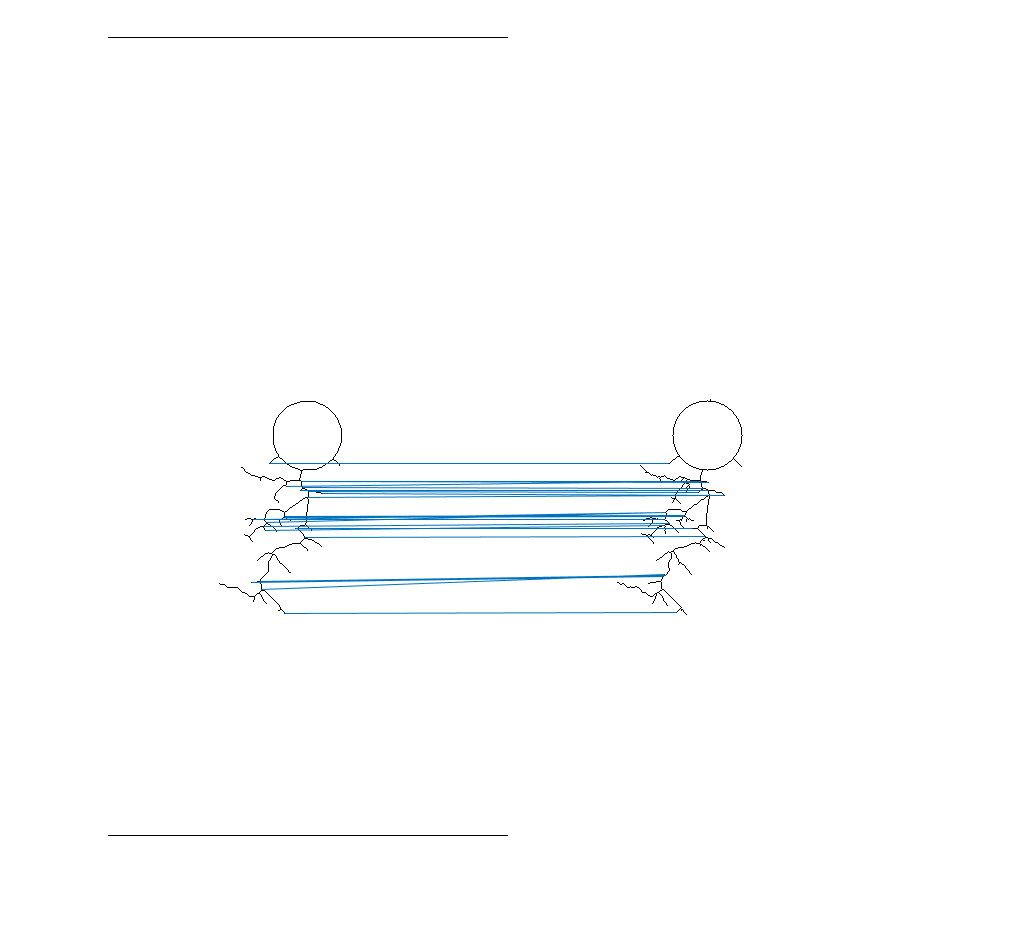

load refIMG.mat
load testIMG.mat
[matchingRate, exactCorrectNum, iter_mat1] = algfixTesting(testIMG, refIMG);

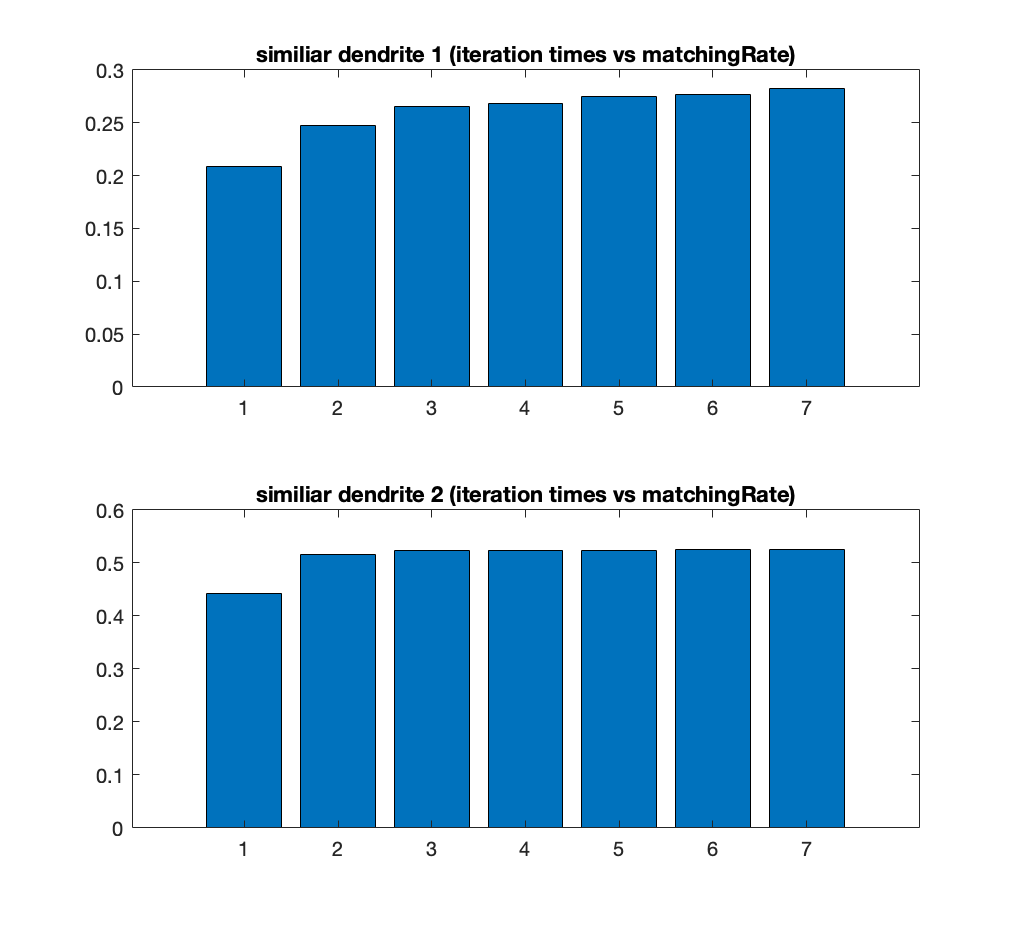

load iter_mat.mat
subplot(2,1,1)
bar(iter_mat)
title('similiar dendrite 1 (iteration times vs matchingRate)')
subplot(2,1,2)
bar(iter_mat1)
title('similiar dendrite 2 (iteration times vs matchingRate)')

Center1 at [400, 400], radius = 3.450000e+01
Center1 at [401, 401], radius = 3.450000e+01
the last matchingRate Difference is 8.930000e+01 !
the last matchingRate Difference is 5.830000e+00 !
the last matchingRate Difference is 5.830000e-01 !
the last matchingRate Difference is 1.110000e-01 !
the last matchingRate Difference is 3.000000e-02 !
the last matchingRate Difference is 1.030000e-02 !
the last matchingRate Difference is 4.220000e-03 !


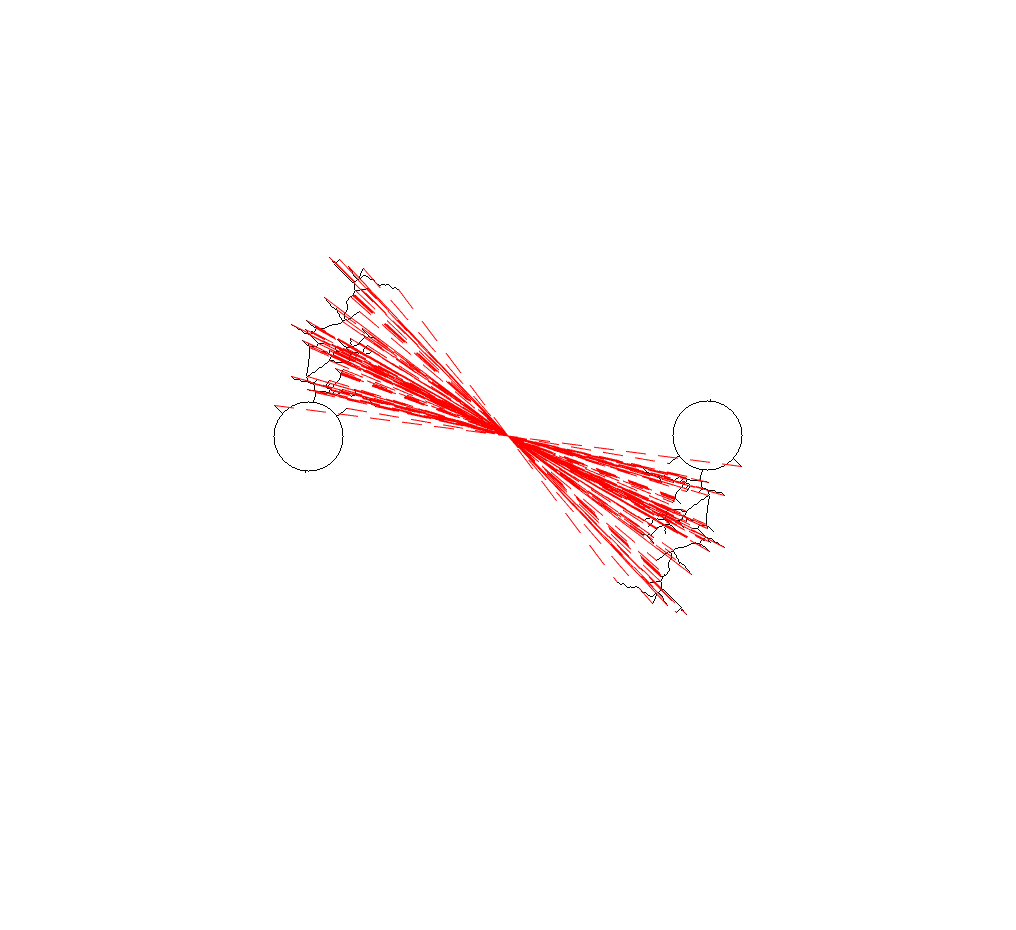

H_mat =    -0.0009   -0.0000    0.7071
    0.0000   -0.0009    0.7071
    0.0000   -0.0000    0.0009


H_mat =     0.0009   -0.0000   -0.7071
   -0.0000    0.0009   -0.7071
   -0.0000   -0.0000   -0.0009


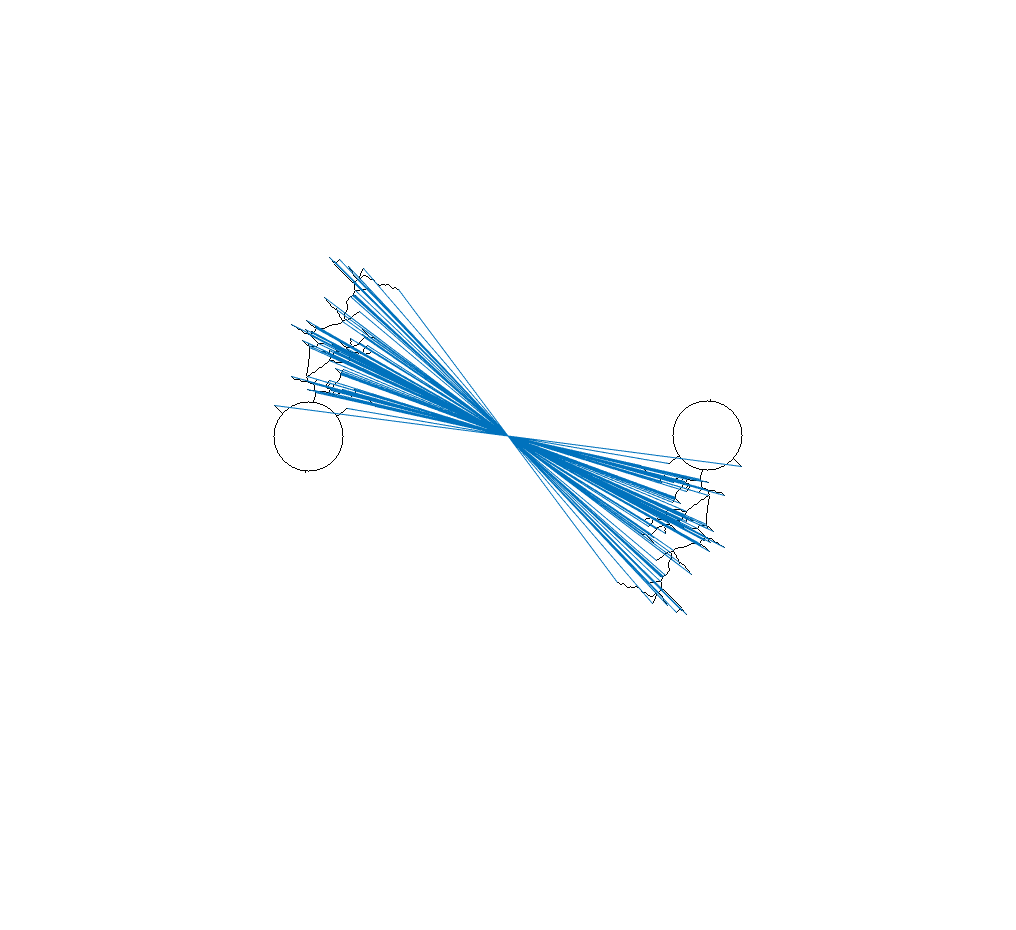

ans = 0.9514

load('refIMG.mat')
rot = imrotate(refIMG,180);
algfixTesting(rot, refIMG)